# Density profiles from tilt measurements

M.P.Ross

## Properties of Rayleigh Waves:

Elastic seismic waves have six independent component, three translational $(u_x, u_y, u_z)$ and three rotational$(\theta_x,\theta_y,\theta_z)$. Traditional seismology only utilizes the three translational components but with the development of devices that sense purely the rotational degrees of freedom new information is available. Below are equations for the six components of a plane Rayleigh wave in a flat half space:


$$u_x({\bf r} ,t)=\alpha sin(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_y({\bf r} ,t)=\alpha sin(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_z({\bf r} ,t)=\alpha cos(\zeta) cos(\omega t-{\bf k}\cdot{\bf r}+\pi/2 + \phi)\\
\\
\theta_x({\bf r} ,t)=\frac{\partial u_z}{\partial y}=\alpha \kappa cos(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_y({\bf r} ,t)=-\frac{\partial u_z}{\partial x}=-\alpha \kappa cos(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_z({\bf r} ,t)=\frac{1}{2}\Big(\frac{\partial u_y}{\partial x}-\frac{\partial u_x}{\partial y}\Big)=0$$


Due to the complex nature of earthquake events, true seismic measurements are far from individual plane waves. However, if we decompose the measured signal into the Fourier domain we get simple equations for the amplitudes at a given frequency:


$$\dot{u_z}=\alpha \omega cos(\zeta)\\
\theta_x=\alpha \kappa cos(\zeta) sin(\psi)\\
\theta_y=\alpha \kappa sin(\zeta) cos(\psi)\\$$


Where the dot represents the time derivative. These can be easily recast into geologically interesting parameters, the Rayleigh wave phase velocity $\nu$ and the angle of incidence $\psi$ of the seismic wave. Here we will only analyze the phase velocity since this encoded the local density profile.


$$\nu\equiv \frac{\omega}{\kappa}=\frac{\dot{u_z}}{\sqrt{\theta_x^2+\theta_y^2}}\\
\psi=arctan\frac{\theta_x}{\theta_y}$$


velocityProfileDataLoad;

ans = "Mexico_5_9"

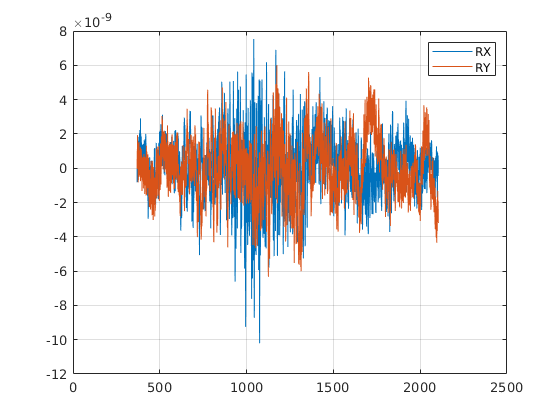


%% Spectra
avg=9;
[ABRSX, ~] = asd2(BRSX,1/sampF, avg, 1, @hann);
[ABRSY, ~] = asd2(BRSY,1/sampF, avg, 1, @hann);
[ASTSX, ~] = asd2(STSX,1/sampF, avg, 1, @hann);
[ASTSY, ~] = asd2(STSY,1/sampF, avg, 1, @hann);
[ASTSZ, F] = asd2(STSZ,1/sampF, avg, 1, @hann);

[COH,~]=coh2(BRSX,BRSY,1/sampF, avg, 1, @hann);
[COHX,~]=coh2(BRSX,STSZ,1/sampF, avg, 1, @hann);
[COHY,F2]=coh2(BRSY,STSZ,1/sampF, avg, 1, @hann);

[T,~]=tfe2(sqrt(BRSX.^2+BRSY.^2),STSZ,1/sampF, avg, 1, @hann);
[TX,~]=tfe2(BRSX,STSZ,1/sampF, avg, 1, @hann);
[TY,F3]=tfe2(BRSY,STSZ,1/sampF, avg, 1, @hann);

plot(time,BRSY,time,BRSX);
grid on
legend('RX','RY')

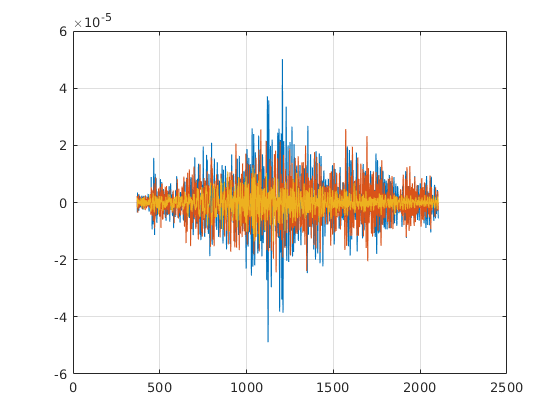


plot(time,STSX,time,STSY,time,STSZ);
grid on

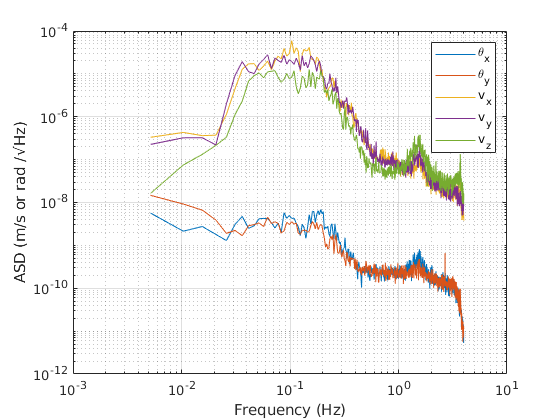


loglog(F,ABRSY,F,ABRSX,F,ASTSX,F,ASTSY,F,ASTSZ);
grid on
ylabel('ASD (m/s or rad /\surd{Hz})')
xlabel('Frequency (Hz)')
legend('\theta_x','\theta_y','v_x','v_y','v_z')

%% Phase Velocity Calculations

thresh=0.8;
Cin=find(and(sqrt(COHX.^2+COHY.^2)>thresh,F2<0.5));
cohV=ASTSZ(Cin)./sqrt(ABRSY(Cin).^2+ABRSX(Cin).^2);
% cohV=abs(real(T(Cin)));
cohF=F(Cin);
vel=[vel; cohV];
vFreq=[vFreq; cohF];

obsDispers=movmean(vel,40);
depth=obsDispers./vFreq;


$$(\nu/v_t)^6-8(\nu/v_t)^4+8(\nu/v_t)^2(3-2 (\frac{v_t}{v_l})^2)-16(1-(\frac{v_t}{v_l})^2)=0$$


%% Fit
layers=3;
[bestPar,bestDispers,frames]=dispersionFit(vFreq,vel,layers);

Error: File: dispersionFit.m Line: 181 Column: 1
This statement is not inside any function. 
 (It follows the END that terminates the definition of the function "dispersionFit".)

if(layers==3)
    bestDepth=bestPar(1)*heaviside(-(1:5e4)+bestPar(3))+bestPar(4)*heaviside(-(1:5e4)+bestPar(6)).*heaviside((1:5e4)-bestPar(3))+bestPar(7)*heaviside((1:5e4)-bestPar(6));
elseif(layers==2)
    bestDepth=bestPar(1)*heaviside(-(1:5e4)+bestPar(3))+bestPar(4)*heaviside((1:5e4)-bestPar(3));
end



$$\rho=1.6612 v_l-0.4721 v_l +0.067 v_l^3-0.0043 v_l^4+0.000106 v_l^5$$


plot(vFreq,vel,'.',vFreq,bestDispers);
ylabel('Velocity (m/s)')
xlabel('Frequency (Hz)')

plot(bestDepth,-(1:5e4)/1e3);
xlabel('Velocity (m/s)')
ylabel('Depth (km)')
ylim([-40 0])

bestDepth=bestDepth/1e3;
dens=1.6612*bestDepth-0.4721*bestDepth.^2+0.0671*bestDepth.^3-0.0043*bestDepth.^4+0.000106*bestDepth.^5;

plot(dens,-(1:5e4)/1e3,1.3+0*(1:5e4),-(1:5e4)/1e3,2.65+0*(1:5e4),-(1:5e4)/1e3);
xlabel('Density (g/cm^3)')
ylabel('Depth (km)')

legend('Measured','Density of silt loam soil','Density of quartz')
xlim([1 3])
ylim([-40 10])
